# ME5554/AOE5754/ECE5754 Applied Linear Systems - Midterm Project

name: Md Riasat Morshed Khan

date: 11/18/2024

## Background

A small startup company is developing an alternative Reusable Launch Vehicle for taking satellites into space.  As shown in Figure 1 below, this launch vehicle is 65m tall and has a base that is 20m wide.  The CG of this vehicle is 20m above the ground.  For this analysis, we will only consider a 2D model of the vehicle, so all motions will exist in the x-y plane.  Note that some of the dimensions below will not be useful, and are only provided for context.

The diagram on the right of Figure 1 shows the coordinate system definition with the two control inputs.

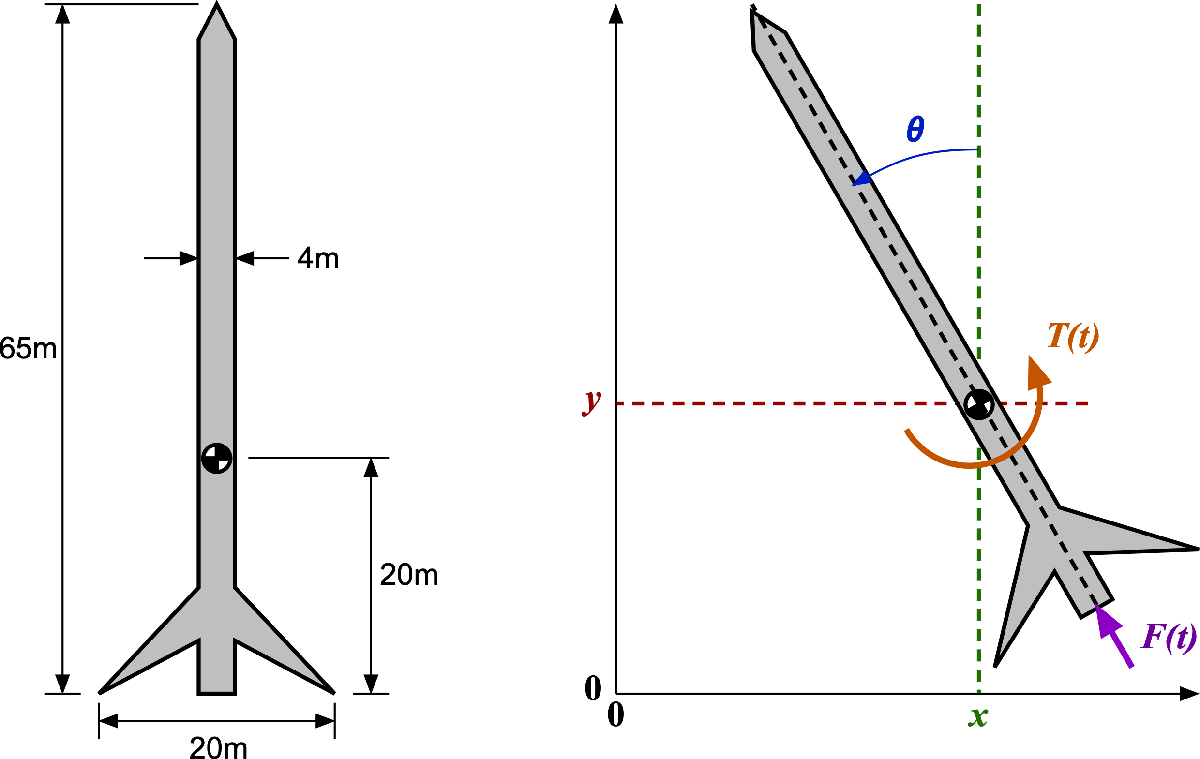

**Figure 1.  Reusable Launch Vehicle dimensions and 2D-Coordinate System Definition**

The following definitions refer to Figure 1:

        
$$\begin{array}{l}
\textrm{CG}=\textrm{center}\;\textrm{of}\;\textrm{gravity}\;\textrm{of}\;\textrm{the}\;\textrm{system}\;\textrm{with}\;\textrm{the}\;\textrm{current}\;\textrm{payload}\;\textrm{position}\\
O,O=\textrm{origin}\;\textrm{of}\;\textrm{the}\;\textrm{world}\;\textrm{coordinate}\;\textrm{system}\\
x\left(t\right)=\textrm{horizontal}\;\textrm{position}\;\left\lbrack \textrm{meters}\right\rbrack \;\textrm{of}\;\textrm{the}\;\textrm{CG}\;\textrm{in}\;\textrm{the}\;\textrm{world}\;\textrm{coordinate}\;\textrm{system}\\
y\left(t\right)=\textrm{vertical}\;\textrm{position}\;\left\lbrack \textrm{meters}\right\rbrack \;\textrm{of}\;\textrm{the}\;\textrm{CG}\;\textrm{in}\;\textrm{the}\;\textrm{world}\;\textrm{coordinate}\;\textrm{system}\\
\theta \left(t\right)=\textrm{angular}\;\textrm{position}\;\left\lbrack \textrm{radians}\right\rbrack \;\textrm{of}\;\textrm{the}\;\textrm{vehicle}\;\textrm{relative}\;\textrm{to}\;\textrm{vertical}\;\left(\textrm{positive}\;\textrm{angles}\;\textrm{are}\;\textrm{CCW}\right)\\
F\left(t\right)=\;\textrm{control}\;\textrm{thrust}\;\textrm{force}\;\left\lbrack \textrm{Newtons}\right\rbrack \;\textrm{at}\;\textrm{the}\;\textrm{base}\;\textrm{of}\;\textrm{the}\;\textrm{vehicle},\textrm{always}\;\textrm{parallel}\;\textrm{to}\;\textrm{the}\;\textrm{vehicle}\;\textrm{axis}\\
T\left(t\right)=\;\textrm{control}\;\textrm{moment}\;\left\lbrack \textrm{Newton}\ldotp \textrm{meters}\right\rbrack \;\textrm{operating}\;\textrm{at}\;\textrm{the}\;\textrm{CG}\;\left(\textrm{positive}\;\textrm{moments}\;\textrm{are}\;\textrm{CCW}\right)
\end{array}$$


The assumed equations of motion for this system are non-linear because they have transcendental terms as well as products of time-varying terms:

        Force balance, y-direction:      $M\ddot{\mathrm{y}} \left(t\right)=F\left(t\right)\cos \theta \left(t\right)-\alpha \dot{y} \left(t\right)-M\;g\;$  

        Moment balance about CG:    $J\ddot{\theta} \left(t\right)=T\left(t\right)-\beta \dot{\theta} \left(t\right)$  

        Force balance, x-direction:     $M\ddot{x} \left(t\right)=-F\left(t\right)\sin \theta \left(t\right)-\gamma \dot{x} \left(t\right)$ 

The parameters associated with these ODEs are defined to be:

        
$$\begin{array}{l}
g=\textrm{gravity}\;\left\lbrack \frac{m}{s^2 }\right\rbrack \\
M=\textrm{total}\;\textrm{mass}\;\left\lbrack \textrm{kg}\right\rbrack \;\textrm{of}\;\textrm{the}\;\textrm{launch}\;\textrm{vehicle}\\
J=\textrm{total}\;\textrm{rotational}\;\textrm{moment}\;\textrm{of}\;\textrm{inertia}\;\left\lbrack \textrm{kg}\cdot m^2 \right\rbrack \;\textrm{of}\;\textrm{the}\;\textrm{launch}\;\textrm{vehicle}\;\textrm{about}\;\textrm{the}\;\textrm{CG}\\
\alpha =\textrm{vertical}\;\textrm{aerodynamic}\;\textrm{damping}\;\textrm{coefficient}\;\;\left\lbrack \frac{N\cdot s}{\;m}\right\rbrack \\
\beta =\textrm{rotational}\;\textrm{aerodynamic}\;\textrm{damping}\;\textrm{coefficient}\;\left(\frac{N\cdot m\cdot s}{\textrm{rad}}\right)\\
\gamma =\textrm{horizontal}\;\textrm{aerodynamic}\;\textrm{damping}\;\textrm{coefficient}\;\left(\frac{N\cdot s}{m}\right)
\end{array}$$


## Problem 1 [6 pts].  Linearization of the Nonlinear Equations of Motion

To linearize this system, you will need to use a multi-step approach.  For the first step, you will use a "Small Angle Approximation" to eliminate the transcendental terms.  You can reasonably assume that the vehicle angle $\theta$ relative to vertical is always small:  $\left|\theta \right|<0\ldotp 5236\;\left({\textrm{or}\;30}^{\circ } \right)$.  (Make sure this is the case in your simulations!)  Using the small angle approximation, we know from Taylor series expansions that $\sin \theta \approx \theta$ and $\cos \theta \approx 1$.

**a)** Substitute these approximations into the nonlinear equations of motion to eliminate the transcendental functions, and write the new resulting equations.

## Answer:

Force balance, y-direction:      $M\ddot{\mathrm{y}} \left(t\right)=F\left(t\right)\times 1-\alpha \dot{y} \left(t\right)-M\;g\;$ 

Moment balance about CG:    $J\ddot{\theta} \left(t\right)=T\left(t\right)-\beta \dot{\theta} \left(t\right)$ 

Force balance, x-direction:     $M\ddot{x} \left(t\right)=-F\left(t\right)\theta \left(t\right)\;-\gamma \dot{x} \left(t\right)$ 

**b)**  After applying the small angle approximation, one of the equations of motion in part 1a will still have a product of time-varying signals, and one of the equations will have a constant input, which does not fit the conventional state-space modeling framework.  To eliminate the nonlinear term and the constant term, we first need to recognize that when the launch vehicle is in **equilibrium**, it is not moving, i.e. $x\left(t\right)=\textrm{constant}$, $y\left(t\right)=\textrm{constant}$, and $\theta \left(t\right)=0$; therefore, all of the derivatives of these coordinates will be zero in the equilibrium state. 

Write the equations of motion at the equilibrium condition and solve for the steady state control inputs $F\left(t\right)=F_{\textrm{ss}}$ and $T\left(t\right)=T_{\textrm{ss}}$ that satisfy all three equations.  These steady-state values represent the nominal constant thrust and constant moment required to maintain equilibrium at any point in the 2D plane.

## Answer:

For equilibrium state,

Force balance, y-direction: $\begin{array}{l}
0=F_{\textrm{ss}} -\alpha \times 0-M\;g\\
\Rightarrow F_{\textrm{ss}} =M\;g
\end{array}$

Moment balance about CG:    $\begin{array}{l}
0=T_{\textrm{ss}} -0\\
\Rightarrow T_{\textrm{ss}} =0
\end{array}$

So, $\begin{array}{l}
F\left(t\right)=F_{\textrm{ss}} +f\left(t\right)=M\;g+f\left(t\right)\\
T\left(t\right)=T_{\textrm{ss}} +\tau \;\left(t\right)=0+\tau \;\left(t\right)
\end{array}$

**c)**  Next, you will need to redefine the control inputs in terms of these steady-state values using a "variational" form:

        
$$F\left(t\right)\equiv F_{\textrm{ss}} +f\left(t\right)$$


        
$$T\left(t\right)\equiv T_{\textrm{ss}} +\tau \left(t\right)$$


where $f\left(t\right)$ is a variational control thrust, and $\tau \left(t\right)$ is a variational control moment that will be the new control inputs to your linearized state-space model.  Substitute these definitions into the equations of motion along with the definitions of the steady-state values from 1b):

## Answer:

Therefore, the equations take the following form:

Force balance, y-direction:      $\begin{array}{l}
M\ddot{\mathrm{y}} \left(t\right)=M\;g+f\left(t\right)-\alpha \dot{y} \left(t\right)-M\;g\\
M\;\ddot{\mathrm{y}} \;\left(t\right)=f\left(t\right)-\alpha \dot{y} \left(t\right)
\end{array}$

Moment balance about CG:    $J\ddot{\theta} \left(t\right)=\tau \;\left(t\right)-\beta \dot{\theta} \left(t\right)$

Force balance, x-direction:     $M\ddot{x} \left(t\right)=-\left(M\;g+f\left(t\right)\right)\theta \left(t\right)\;-\gamma \dot{x} \left(t\right)$

**d)**  At this point, all of the following should be true:

- none of the ODEs have $F\left(t\right)$ or $T\left(t\right)$ in the equations

- the only control inputs to any of the ODEs should be $f\left(t\right)$ or $\tau \left(t\right)$

- two of the three ODEs are completely linear

- one of the three ODEs still has a nonlinear term (product of two time-varying quantities)

To eliminate the final nonlinearity, we can recognize that the variational control signal $f\left(t\right)$ will be much "smaller" than the steady-state thrust: $\left|f\left(t\right)\right|\ll F_{\textrm{ss}}$.  Leveraging this assumption, you can assume that $f\left(t\right)\approx 0$ to eliminate the non-linear term.  Note that you CANNOT apply this assumption in the other ODEs from 1c) above!  Write out the final three linearized ODEs for the reusable launch vehicle:

## Answer:

Force balance, y-direction:      $\begin{array}{l}
M\ddot{\mathrm{y}} \left(t\right)=M\;g+f\left(t\right)-\alpha \dot{y} \left(t\right)-M\;g\\
M\;\ddot{\mathrm{y}} \;\left(t\right)=f\left(t\right)-\alpha \dot{y} \left(t\right)
\end{array}$

Moment balance about CG:    $J\ddot{\theta} \left(t\right)=\tau \;\left(t\right)-\beta \dot{\theta} \left(t\right)$

Force balance, x-direction:     $\begin{array}{l}
M\ddot{x} \left(t\right)=-\left(M\;g+f\left(t\right)\right)\theta \left(t\right)\;-\gamma \dot{x} \left(t\right)\\
M\ddot{x} \left(t\right)=-M\;g\;\theta \left(t\right)\;-\gamma \dot{x} \left(t\right)
\end{array}$

## Problem 2 [6 pts].  Analytic State-Space Model

Using the linearized equations of motion from Problem 1d), choose appropriate state variables and CLEARLY define a complete state-space representation for this system.  You must assume that the ONLY outputs are $\left(x,y,\theta \right)$ because these are easily measured signals.  You already know that the ONLY control inputs are $\left(f,\tau \right)$.

## Answer:

If we organize the equation in state-space format, then:

Force balance, y-direction:      $\begin{array}{l}
M\ddot{\mathrm{y}} \left(t\right)=M\;g+f\left(t\right)-\alpha \dot{y} \left(t\right)-M\;g\\
\ddot{\mathrm{y}} \;\left(t\right)=\frac{f\left(t\right)}{M}-\frac{\alpha }{M}\dot{y} \left(t\right)
\end{array}$

Moment balance about CG:    $\ddot{\theta} \left(t\right)=\frac{\tau \left(t\right)}{\;J}-\frac{\beta }{J}\dot{\theta} \left(t\right)$

Force balance, x-direction:     $\begin{array}{l}
M\ddot{x} \left(t\right)=-M\;g\;\theta \left(t\right)\;-\gamma \dot{x} \left(t\right)\\
\ddot{x} \left(t\right)=-g\;\theta \left(t\right)\;-\frac{\gamma }{M}\dot{x} \left(t\right)
\end{array}$

Now, let, $\begin{array}{l}
x_1 =x\\
x_2 =\dot{\;x\;} =\dot{\;x_1 } \\
x_{3\;} =y\\
x_4 =\dot{\;y\;} =\dot{\;x_3 } \\
x_5 =\theta \;\\
x_{6\;} =\dot{\;\theta \;} =\dot{\;x_{5\;} } 
\end{array}$

So we can write our state-space model as:


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\dot{\;x_1 } \\
\dot{\;x_2 } \\
\dot{\;x_3 } \\
\dot{\;x_4 } \\
\dot{\;x_5 } \\
\dot{\;x_6 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
0 & 1 & 0 & 0 & 0 & 0\\
0 & -\frac{\gamma }{M} & 0 & 0 & -g & 0\\
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & -\frac{\alpha }{M} & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & 0 & 0 & 0 & \frac{\beta }{J}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 \\
x_5 \\
x_6 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
0 & 0\\
\frac{1}{M} & 0\\
0 & 0\\
0 & \frac{1}{J}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
f\left(t\right)\\
\tau \left(t\right)
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack =\;\left\lbrack \begin{array}{cccccc}
1 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 \\
x_5 \\
x_6 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
f\left(t\right)\\
\tau \left(t\right)
\end{array}\right\rbrack 
\end{array}$$


## Problem 3 [2 pts].  Define system parameters as Matlab variables

Up to this point, you should have only used algebraic symbols to describe parameters in the state-space model.  It is now time to substitute numerical values for these parameters in the Matlab workspace.  Define variables in Matlab with the following numerical values:

        
$$\begin{array}{l}
g=9\ldotp 81\;\left(m/s^2 \right)\\
M=550000\;\left(\textrm{kg}\right)\;\\
L=65\;\left(m\right)\\
J=\frac{1}{8}{M\;L}^2 \;\left(\textrm{kg}\;{\;m}^2 \right)\;\\
\alpha =33\textrm{e5}\;\left(N\;s/m\right)\\
\beta =8\ldotp 714\textrm{e8}\;\left(N\;m\;s/\textrm{rad}\right)\\
\gamma =11\textrm{e5}\;\left(N\;s/m\right)\\
F_{\max } =20\textrm{e7}\;\left(N\right)\;\;\;\;\;\textrm{maximum}\;\textrm{total}\;\textrm{thrust}:\;\left|F\left(t\right)\right|\le F_{\max } \\
T_{\max } =20\textrm{e7}\;\left(N\;m\right)\;\;\;\;\;\textrm{maximum}\;\textrm{total}\;\textrm{moment}:\;\;\left|T\left(t\right)\right|\le T_{\max } 
\end{array}$$


## Answer

alpha = 33e5; %in Ns/m
M = 55e4; % in kg
L = 65; % in m
J = 1/8*M*L^2;
beta = 8.714e8;
gamma = 11e5;
g = 9.8;

Compute the nominal equlibrium thrust force ($F_{\textrm{ss}}$) and moment ($T_{\textrm{ss}}$), and then compute the maximum variational control forces and moments.

$f_{\textrm{mi}n} \le f\left(t\right)\le f_{\max }$     and     $\tau_{\min } \le \tau \left(t\right)\le \tau_{\max }$

## Answer

Given that $\begin{array}{l}
|F\left(t\right)|\le F_{\max } \\
\Rightarrow |F_{\textrm{ss}} +f\left(t\right)|<20\times {10}^7 \\
\Rightarrow |M\;g+f\left(t\right)|\le 20\times {10}^7 \\
\Rightarrow -20\times {10}^7 \le M\;g+f\left(t\right)\le 20\times {10}^7 \\
\Rightarrow -20\times {10}^7 -55\times {10}^4 \times 9\ldotp 81\le f\left(t\right)\le 20\times {10}^7 -55\times {10}^4 \times 9\ldotp 81\\
\Rightarrow -2\ldotp 054\times {10}^{\;8} \le f\left(t\right)\le 1\ldotp 946\times {10}^{8\;} 
\end{array}$

Given that $\begin{array}{l}
|T\left(t\right)|\le T_{\max } \\
\Rightarrow |T_{\textrm{ss}} +\tau \;\left(t\right)|\le 20\times {10}^7 \\
\Rightarrow |0+\tau \;\left(t\right)|\le 20\times {10}^7 \\
\Rightarrow -20\times {10}^7 \le \tau \;\left(t\right)\le 20\times {10}^7 
\end{array}$ 

## Problem 4 [6 pts].   Numerical State-space model with state, input, and output names

Construct a numerical LTI State-Space object in Matlab using the defined numerical variables from Problem 3.  Do NOT manually type in numerical values for the parameters!

## Answer

A = [0 1 0 0 0 0;0 -gamma/M 0 0 -g 0;0 0 0 1 0 0;0 0 0 -alpha/M 0 0;0 0 0 0 0 1;0 0 0 0 0 -beta/J]

A =          0    1.0000         0         0         0         0
         0   -2.0000         0         0   -9.8000         0
         0         0         0    1.0000         0         0
         0         0         0   -6.0000         0         0
         0         0         0         0         0    1.0000
         0         0         0         0         0   -3.0000


B = [0 0;0 0;0 0;1/M 0;0 0;0 1/J];
C = [1 0 0 0 0 0;0 0 1 0 0 0;0 0 0 0 1 0];
D = [0 0;0 0;0 0];
sys = ss(A,B,C,D);
sys.StateName={'Horz Postion','Horz Velocity','Vert Postion','Vert Velocity', 'Rot Position','Rot Velocity'};
sys.InputName={'Force','Torque'};
sys.OutputName={'Horz Position','Vert Position','Rot Position'};
sys.StateUnit={'meters','meters/second','meters','meters/second','radians','radians/second'};
sys.InputUnit={'Newtons','Newtons-meters'};
sys.OutputUnit={'meters','meters','radians'};

Next, define the 'StateName', 'InputName', and 'OutputName' properties of your LTI state-space object with strings that are representative of the actual states, inputs, and outputs.  You may also want to define the StateUnit, InputUnit, and OutputUnit properties as well (not required but may come in handy later...)

Note:  Names such as {x1, x2, x3, y1, y2, y3, u1, u2} are NOT considered representative of the actual states, inputs, or outputs!!!  These are the default labels that Matlab assigns automatically, so you are required to rename these to match your selection of actual states, outputs, and inputs.

sys.StateName

ans = 6×1 cell array
    {'Horz Postion' }
    {'Horz Velocity'}
    {'Vert Postion' }
    {'Vert Velocity'}
    {'Rot Position' }
    {'Rot Velocity' }


Display your final numerical state-space model and save it to a .mat file for use in the Final Project.  Unless you make a mistake, this model will NOT be changed after this point.

save('sys.mat')

## Problem 5 [2 pts].  Check your model for a minimum realization

Use the `MINREAL()` function to demonstrate that your system is a minimum realization.  It is NOT sufficient to simply call the `MINREAL` function!  You will need to explain why your system is a minimum realization.

## Answer:

minimum_real = minreal(sys);
if isequal(sys,minimum_real)
    disp('This is minimum realization')
end

This is minimum realization


## **Explanation:**

If we write out the state-space realization, this will look like the following:


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\dot{\;x_1 } \\
\dot{\;x_2 } \\
\dot{\;x_3 } \\
\dot{\;x_4 } \\
\dot{\;x_5 } \\
\dot{\;x_6 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
0 & 1 & 0 & 0 & 0 & 0\\
0 & -\frac{\gamma }{M} & 0 & 0 & -g & 0\\
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & -\frac{\alpha }{M} & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & 0 & 0 & 0 & \frac{\beta }{J}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 \\
x_5 \\
x_6 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
0 & 0\\
\frac{1}{M} & 0\\
0 & 0\\
0 & \frac{1}{J}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
f\left(t\right)\\
\tau \;\left(t\right)
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack =\;\left\lbrack \begin{array}{cccccc}
1 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 \\
x_5 \\
x_6 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
f\left(t\right)\\
\tau \left(t\right)
\end{array}\right\rbrack 
\end{array}$$


If we look at the state-space equation, we can see that there is not such state which can be thrown out the of the equation. Meaning, there is no corresponding column of any state that is entirely 0. 

For example, if we think of the 3rd column of the A matrix, we will notice that it is entirely 0 and therefore, we might be tempted to think that $x_3$ can be eliminated. However, if we look at the corresponding column of C matrix, we notice that there is an 1 there so we can't just throw $x_3$ off. 

If we think in terms of what $\textrm{minreal}\left(\right)$outputs, we can see that the variable $\textrm{minimum}\_\textrm{real}\;$has a dimension that exactly matches with the original *sys *variable, meaning, there is not "unnecessary" present there. Also, I used *isequal() *function to show that our state-space representation is of minimum realization

## Problem 6 [4 pts].  Controllability test

Demonstrate that your open-loop LTI model is completely controllable using all actuators.  Check the controllability of all subsets of actuators.  Explain your results.

## Answer:

Co = ctrb(sys)

Co =          0         0         0         0         0         0         0   -0.0000         0    0.0000         0   -0.0000
         0         0         0         0         0   -0.0000         0    0.0000         0   -0.0000         0    0.0000
         0         0    0.0000         0   -0.0000         0    0.0001         0   -0.0004         0    0.0024         0
    0.0000         0   -0.0000         0    0.0001         0   -0.0004         0    0.0024         0   -0.0141         0
         0         0         0    0.0000         0   -0.0000         0    0.0000         0   -0.0000         0    0.0000
         0    0.0000         0   -0.0000         0    0.0000         0   -0.0000         0    0.0000         0   -0.0000


N = size(sys.A,1);
M = size(sys.B,2);
P = size(sys.C,1);

count = 1;
for number_of_inputs = 1:M
    indx = nchoosek([1:M],number_of_inputs);
    K = size(indx,1);
    for k = 1:K
        Q = ctrb(sys(:,indx(k,:)));

        fprintf('rank(Q) = %d, subset = [ ',rank(Q));
        for i = 1:length(indx(k,:))
            fprintf(' u%d ',indx(k,i));
        end
        fprintf(']\n');
        count = count + 1;
    end
end

rank(Q) = 2, subset = [ 

 u1 

]


rank(Q) = 4, subset = [ 

 u2 

]


rank(Q) = 6, subset = [ 

 u1  u2 

]


## Explanation:

The controllability implies that we can drive a system from any initial state ${\mathit{\mathbf{x}}}_0 \left(t_0 \right)$ to any terminal state $\mathit{\mathbf{x}}\left(t\right)$ by our control input $\mathit{\mathbf{u}}\left(t\right)$.

We have 2 input, namely $f\left(t\right)$ and $\tau \;\left(t\right)$. We checked by ctrb() function that if we can drive our system from one state to another will all the combinations of $f\left(t\right)$ and $\tau \;\left(t\right)$, namely, $f\left(t\right)$ only, $\tau \;\left(t\right)$ only and both$f\left(t\right)$ and $\tau \;\left(t\right)$. We found that the system is not controllable with just one input only. It becomes controllable when we use both $f\left(t\right)$ and $\tau \;\left(t\right)$. 

Which is to say that, you cannot drive your system to any initial state to any location in the state-space with just one input. To be able to do that, you need both.

## Problem 7 [2 pts].  Open-loop poles & natural frequencies

Compute the open-loop eigenvalues, damping ratios, time constants, and natural frequencies in Hz.  Construct a table using the Matlab `TABLE()` function, then display a formatted table with appropriate column and row headings in the LiveScript.

## Answer

[eigMat,eigVal] = eig(A);
natFreq_rad = abs(diag(eigVal));
natFreq_Hz = natFreq_rad ./ (2*pi);
dampingRatio = -real(diag(eigVal)) ./natFreq_rad;
timeConst = -1 ./ real(diag(eigVal));
Eigen_Values = diag(eigVal);
Damping_Ratio = dampingRatio;
Time_Constant = timeConst;
NaturalFrequency_Hz = natFreq_Hz;
T = table(Eigen_Values,Damping_Ratio,Time_Constant,NaturalFrequency_Hz)

T = 6×4 table
    Eigen_Values    Damping_Ratio    Time_Constant    NaturalFrequency_Hz
    ____________    _____________    _____________    ___________________

          0              NaN               -Inf                   0      
         -2                1                0.5             0.31831      
          0              NaN               -Inf                   0      
         -6                1            0.16667             0.95493      
          0              NaN               -Inf                   0      
         -3                1            0.33334             0.47746      


## Problem 8 [8 pts].  Open-Loop Initial Value response simulation

Assume that the system starts with the following initial positions and velocities:

    $x\left(0\right)=50$ m, $y\left(0\right)=50$ m, and $\theta \left(0\right)=0$ rad.

    $\dot{x} \left(0\right)=-0\ldotp 1$ m/s, $\dot{y} \left(0\right)=0\ldotp 1$ m/s, and $\dot{\theta} \left(0\right)=-0\ldotp 01$ rad/s.

Use the Matlab `INITIAL` function to compute the initial value response.  Choose a final time that is **ten** times the largest open-loop finite time constant.

Plot the initial value response.  Your single figure window must include three subplots on the left of the figure, one for each of the outputs, and two subplots on the right, one for each control signal.  Note that the control signals for the open-loop system must be zero!

All subplots must be properly annotated with axis labels, units, and grid lines.

The control output plots must also show the upper and lower saturation constraints for the signals using the `YLINE`() function.

Use the `LSIMINFO` function to estimate the 5% settling time for each OUTPUT, and place a marker or a vertical line (`XLINE`) on each output plot at the location of its 5% settling time.

Define the initial condition vector:

## Answer

init_vector = [50,-0.1,50,0.1,0,-0.01];
final_t = 10*max(timeConst);
t = linspace(0,final_t,1000);

Simulate the initial value response using `INITIAL()`

[y,tOut] = initial(sys,init_vector,t);

Estimate and display the 5% settling times for each output:

settlingTime_lsim = zeros(size(y,2));
for i = 1:size(y,2)
    S = lsiminfo(y(:,i),tOut,y(end,i),y(1,i),"SettlingTimeThreshold",0.05);
    settlingTime_lsim(i) = S.SettlingTime;
    fprintf('The settling Time for y(%d) is = %2.3f\n',i, S.SettlingTime)
end

The settling Time for y(1) is = 4.945
The settling Time for y(2) is = 0.499
The settling Time for y(3) is = 0.999


Plot the open-loop initial value response:

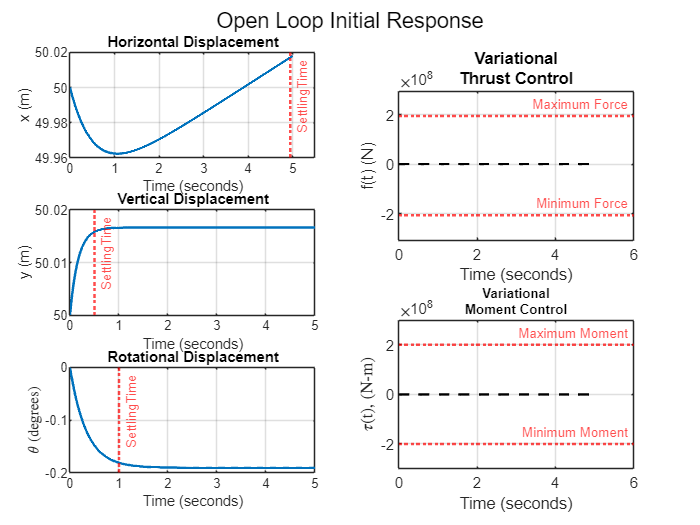

Fmax = 1.946e8;
Tmax = 20e7;
Fmin = -2.054e8;
Tmin = -20e7;
clf;

subplot(3,2,1);
plot(tOut, y(:,1), 'LineWidth', 1.5);
hold on;
xline(settlingTime_lsim(1), 'r:', 'LineWidth', 1.5, 'Label', 'SettlingTime', ...
    'LabelOrientation', 'aligned', 'FontSize', 8);
hold off;
xlim([0, max(tOut) + 0.1*max(tOut)]);
xlabel('Time (seconds)');
ylabel('x (m)');
title('Horizontal Displacement');
grid on;
set(gca, 'Position', [0.1, 0.7, 0.35, 0.2]); % [left, bottom, width, height]


subplot(3,2,3);
plot(tOut, y(:,2), 'LineWidth', 1.5);
hold on;
xline(settlingTime_lsim(2), 'r:', 'LineWidth', 1.5, 'Label', 'SettlingTime', ...
    'LabelOrientation', 'aligned', 'FontSize', 8);
hold off;
xlim([0, max(tOut)]);
xlabel('Time (seconds)');
ylabel('y (m)');
title('Vertical Displacement');
grid on;
set(gca, 'Position', [0.1, 0.4, 0.35, 0.2]);

subplot(3,2,5);
plot(tOut, rad2deg(y(:,3)), 'LineWidth', 1.5);
hold on;
xline(settlingTime_lsim(3), 'r:', 'LineWidth', 1.5, 'Label', 'SettlingTime', ...
    'LabelOrientation', 'aligned', 'FontSize', 8);
hold off;
xlim([0, max(tOut)]);
xlabel('Time (seconds)');
ylabel('$\theta$ (degrees)', 'Interpreter', 'latex');
title('Rotational Displacement');
grid on;
set(gca, 'Position', [0.1, 0.1, 0.35, 0.2]);
% Plot Variational Thrust Control
subplot(2,2,2);
plot(tOut, zeros(1, length(tOut)), 'k--', 'LineWidth', 1.5); % Use dashed line for the zero line
hold on;
yline(Fmax, 'r:', 'LineWidth', 1.5, 'Label', 'Maximum Force', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
yline(Fmin, 'r:', 'LineWidth', 1.5, 'Label', 'Minimum Force', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
hold off;
ylim([Fmin-1e8,Fmax+1e8])
xlabel('Time (seconds)');
ylabel('f(t) (N)');
title({'Variational', 'Thrust Control'});
grid on;
% Plot Variational Moment Control
subplot(2,2,4);

plot(tOut, zeros(1, length(tOut)), 'k--', 'LineWidth', 1.5);
hold on;
yline(Tmax, 'r:', 'LineWidth', 1.5, 'Label', 'Maximum Moment', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
yline(Tmin, 'r:', 'LineWidth', 1.5, 'Label', 'Minimum Moment', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
hold off;
ylim([Tmin-1e8, Tmax+1e8])
xlabel('Time (seconds)');
ylabel('$\tau$(t), (N-m)', 'Interpreter', 'latex');
title({'Variational', 'Moment Control'},'FontSize', 8);
grid on;

sgtitle('Open Loop Initial Response');

Provide a physical explanation for the open-loop response.  

## Answer

First thing which is evident in the above graph is that the system after being disturbed from an initial position which is, by the way, is not origin- settled to a different set of position. Since this is a rigid body motion- not something like a spring motion where the body seeks to come back to the origin, it rather steadied to a different value. For example, we can say, for horizontal displacement, it was intially at x=50m. We noticed that it steadied at somewhere x=50.02m. Same goes for the vertical displacement and rotational displacement. This is indicative of a rigid body motion in a physical sense.

Why does the steady-state response look the way it does?

## Answer

Firstly, the control input, both the thrust and moment are 0 which makes sense because in an open loop plant, since no control signal is input, the graphs are supposed to be 0. 

For the rest of the states, which is, $x,y,\theta \;$we can see that they reached to to constant value upon being disturbed from their initial condition and they remain that way. Which is to say, by visual inspection, we can see that horizontal displacement remained at 50.01m, vertical displacement remained at 50.01m and rotational displacement was steadied at -0.2 degree. 

Point is they did not show any tendency to reach 0 or coming to the origin because this is a rigid body motion. Unless we apply control signals they are not supposed to come back to their initial position if disturbed. And this particular phenomenon is observed in the plot above.

## Problem 9 [14 pts].  Closed-Loop Design Case Study

Design and document **four unique sets of closed-loop pole locations** for full state feedback.

The target design requirements are:

- The 5% settling times for all of the outputs must be less than 200 seconds

- The peak absolute variational control signal must not exceed the saturation limits as defined above

For each design, document the following:

- 5% settling times on each of the output responses

- Peak absolute control for each of the control signals

- Does either of your closed-loop control signals exceed the saturation limits?

- Why you chose this set of pole locations for the design?

You must use the `PLACE` function for each of your designs to compute the state feedback gains.  After computing the state feedback gains, display a table of the closed-loop poles to demonstrate that you successfully placed the poles at the design locations.

Develop a closed-loop LTI model that augments the open-loop output vector with the two control signals, so your closed-loop output equation will have five outputs for plotting.

Use the Matlab `INITIAL` function to compute the initial value response with the same initial condition vector that was used in the open-loop evaluation.

Choose a final time that is 6-10 times the largest open-loop time constant.  You will need to choose this final time such that your responses are sufficiently converged for plotting.

Plot the initial value response.  There must be three subplots on the left of the figure, one for each of the outputs, and two subplots on the right, one for each control signal.  All subplots must be properly annotated with axis labels, units, and grid lines.  The control output plots must also show the upper and lower saturation constraints for the signals.

Use the `LSIMINFO` function to estimate the 5% settling time for each OUTPUT, and place a marker on each output plot at the location of its 5% settling time.

choice1 = [-.1, -0.11, -0.12, -0.13, -0.14, -0.2]; % All real poles- fine
choice2 = [-.1, -0.4, -0.3, -0.13, -0.35, -0.2]; %constant real poles -fine
choice3 = [-0.1400 + 0.1428i,  -0.1400 - 0.1428i,  -0.2100 + 0.2142i,  -0.2100 - 0.2142i,-0.1,-0.2]; %polePlacement(0.7,0.2,1)
choice4 = [-0.0900 + 0.0436i,  -0.0900 - 0.0436i,  -0.1800 + 0.0872i,  -0.1800 - 0.0872i,-0.1,-.15]; %polePlacement(0.9,0.1,1)
T = table(choice1', choice2', choice3', choice4');
T.Properties.VariableNames = {'Pole 1', 'Pole 2', 'Pole 3', 'Pole 4'};

### Table1: Chosen Pole 

disp(T)

    Pole 1    Pole 2       Pole 3           Pole 4    
    ______    ______    _____________    _____________

     -0.1      -0.1     -0.14-0.1428i    -0.09-0.0436i
    -0.11      -0.4     -0.14+0.1428i    -0.09+0.0436i
    -0.12      -0.3     -0.21-0.2142i    -0.18-0.0872i
    -0.13     -0.13     -0.21+0.2142i    -0.18+0.0872i
    -0.14     -0.35      -0.1+0i          -0.1+0i     
     -0.2      -0.2      -0.2+0i         -0.15+0i     



format default
gains1 = place(A,B,choice1);
gains2 = place(A,B,choice2);
gains3 = place(A,B,choice3);
gains4 = place(A,B,choice4);
C1 = [C; -gains1];
C2 = [C; -gains2];
C3 = [C; -gains3];
C4 = [C; -gains4];
D1 = [D; zeros(2,2)];
sys1 = ss(A-B*gains1,B, C1,D1);
sys2 = ss(A-B*gains2,B, C2,D1);
sys3 = ss(A-B*gains3,B, C3,D1);
sys4 = ss(A-B*gains4,B, C4,D1);
eigVal1 = eig(A-B*gains1);
eigVal2 = eig(A-B*gains2);
eigVal3 = eig(A-B*gains3);
eigVal4 = eig(A-B*gains4);
timeConst_1 = -1 ./ real(diag(eigVal1));
timeConst_2 = -1 ./ real(diag(eigVal2));
timeConst_3 = -1 ./ real(diag(eigVal3));
timeConst_4 = -1 ./ real(diag(eigVal4));

tt1 = linspace(0,10*max(timeConst_1(:)),1000);
tt2 = linspace(0,10*max(timeConst_2(:)),1000);
tt3 = linspace(0,10*max(timeConst_3(:)),1000);
tt4 = linspace(0,10*max(timeConst_4(:)),1000);
[y1, tOut1] = initial(sys1,init_vector,tt1);
[y2, tOut2] = initial(sys2,init_vector,tt2);
[y3, tOut3] = initial(sys3,init_vector,tt3);
[y4, tOut4] = initial(sys4,init_vector,tt4);

info1 = lsiminfo(y1,tOut1,y1(end,:),y1(1,:),"SettlingTimeThreshold",0.05);
info2 = lsiminfo(y2,tOut2,y2(end,:),y2(1,:),"SettlingTimeThreshold",0.05);
info3 = lsiminfo(y3,tOut3,y3(end,:),y3(1,:),"SettlingTimeThreshold",0.05);
info4 = lsiminfo(y4,tOut4,y4(end,:),y4(1,:),"SettlingTimeThreshold",0.05);

T = table(eigVal1, eigVal2, eigVal3, eigVal4);
T.Properties.VariableNames = {'Pole 1', 'Pole 2', 'Pole 3', 'Pole 4'};


### Table: Verification of the Pole Placement


disp(T);

    Pole 1    Pole 2       Pole 3           Pole 4    
    ______    ______    _____________    _____________

     -0.2      -0.4     -0.21+0.2142i    -0.18+0.0872i
     -0.1     -0.35     -0.21-0.2142i    -0.18-0.0872i
    -0.14      -0.3      -0.1+0i         -0.09+0.0436i
    -0.12      -0.2      -0.2+0i         -0.09-0.0436i
    -0.13      -0.1     -0.14+0.1428i     -0.1+0i     
    -0.11     -0.13     -0.14-0.1428i    -0.15+0i     



MaxForceSignal = [max(y1(:,4)),max(y2(:,4)),max(y3(:,4)),max(y4(:,4))]';
MaxTorqueSignal = [max(y1(:,5)),max(y2(:,5)),max(y3(:,5)),max(y4(:,5))]';
ST1 = double([info1.SettlingTime])';
ST2 = double([info2.SettlingTime])';
ST3 = double([info3.SettlingTime])';
ST4 = double([info4.SettlingTime])';
T = table(ST1, ST2, ST3,ST4);
T.Properties.VariableNames = {'Pole 1', 'Pole 2', 'Pole 3', 'Pole 4'};
T.Properties.RowNames = {'Horizontal Distance','Vertical Distance', 'Rotational Angle', 'Force', 'Torque'};


### Table: Settling Time For Each Output of Each Pole

disp(T)

                           Pole 1    Pole 2    Pole 3    Pole 4
                           ______    ______    ______    ______

    Horizontal Distance    36.903    42.445    39.046    31.058
    Vertical Distance      45.979    35.838    28.482      28.9
    Rotational Angle        99.37    99.511    99.514    110.85
    Force                  93.243    82.993    71.802    73.044
    Torque                 61.852    68.762    63.483    71.208



T = table(MaxForceSignal, MaxTorqueSignal);
T.Properties.RowNames = {'Pole 1', 'Pole 2', 'Pole 3', 'Pole 4'};


### Table: Maximum Control Signal For Each Pole

disp(T)

              MaxForceSignal    MaxTorqueSignal
              ______________    _______________

    Pole 1         82018          5.4995e+07   
    Pole 2       -1230.1          5.6318e+07   
    Pole 3       -759.21          7.2861e+07   
    Pole 4        247.81          6.0225e+07   



## Why did I chose the poles as it is defined?

The thought process is outlined as follows:

**First**, I noticed that 5% settling time is bound to be less than 200s. That essentially means that the real part of the pole has to be  less than 0.015 by using the formula $\begin{array}{l}
t_{5%} =\frac{3}{\zeta \;\omega \;}\\
\Rightarrow -200=-\frac{3}{\zeta \;\omega \;}\\
\Rightarrow -\zeta \;\omega <\;-0\ldotp 015
\end{array}$

**First Pole:** I started out with all real valued pole. After pretty decent amount of trial and error I reached at $\left\lbrack -\ldotp 1,-0\ldotp 11,-0\ldotp 12,-0\ldotp 13,-0\ldotp 14,-0\ldotp 2\right\rbrack$ this set of number that met the criteria. As it is seen that the values are sort of ascdending in terms of order because I was trying to see if this increasing or decreasing real valued number can meet the design criteria. This one worked!

**Second Pole:** While I was doing trial and error for all real-valued poles, this set $\left\lbrack -\ldotp 1,-0\ldotp 4,-0\ldotp 3,-0\ldotp 13,-0\ldotp 35,-0\ldotp 2\right\rbrack$ stood out as the one that meet the design criteria. However, this is not chosen randomly too. I was trying to see as opposed to first set where all the values are near to -0.1, what if I move them further to the left. I would like to report here that if every points are moved further to the left, then the design requirement can not be met. So by trial and error, I introduced some lower values in that set and finally that met the design requirement. 

**Third Pole:** Here, I would like to mention that to make the pole searching easier, I have written a MATLAB function that takes the input of damping ratio and frequency value and a logical value whethere it will look for constant frequency poles or constant damping poles. I found that, if I select my poles solely based on constant frequency or constant damping, this does not work I have to introduce a real valued pole (probably complex number too!) to meet the design requirement. Just for your reference, I will be adding my code as an appendix in this .pdf. 

So, the third pole, that is, $\left\lbrack -0\ldotp 1400+0\ldotp 1428i,-0\ldotp 1400-0\ldotp 1428i,-0\ldotp 2100+0\ldotp 2142i,-0\ldotp 2100-0\ldotp 2142i,-0\ldotp 1,-0\ldotp 2\right\rbrack$ is selected as having a damping ratio ($\zeta \;$) of 0.7 and the frequency($\omega \;$) ranges from 0.2 to 0.3. It is seen that the last two poles are just real valued. This is because if I use the value with frequency 0.4, then it does not meet the design criteria. That is why, I did trial and error with different negative real number.

**Fourth Pole:** The fourth one $\left\lbrack -0\ldotp 0900+0\ldotp 0436i,-0\ldotp 0900-0\ldotp 0436i,-0\ldotp 1800+0\ldotp 0872i,-0\ldotp 1800-0\ldotp 0872i,-0\ldotp 1,-\ldotp 15\right\rbrack$ is obtained by somewhat similar procedure. But this time I went with the constant damping of 0.9  and the frequency goes from 0.1 to 0.2. If I use the complex conjugate pair associated with 0.3 along with these, the design requirement is not met. Hence, again, I introduced two randomly chosen real valued number to meet the requirements.

I would like to report here that I tried some poles with constant frequency but I could not come up with a set that works fine while maintaining the requirement. 

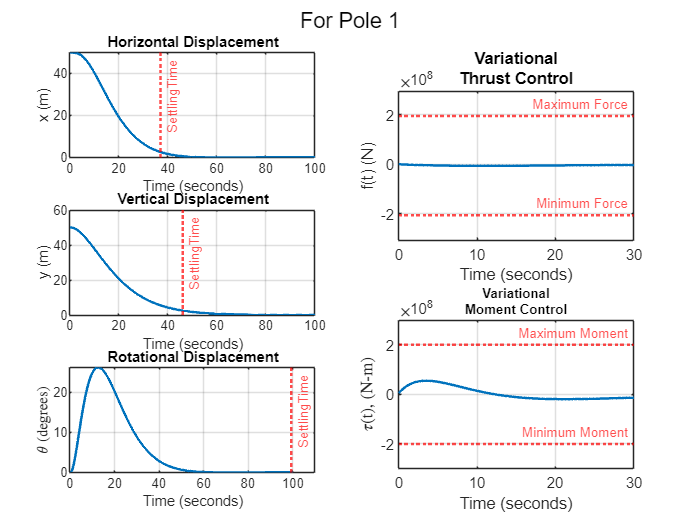

clf;

subplot(3,2,1);
plot(tOut1, y1(:,1), 'LineWidth', 1.5);
hold on;
xline(ST1(1,1), 'r:', 'LineWidth', 1.5, 'Label', 'SettlingTime', ...
    'LabelOrientation', 'aligned', 'FontSize', 8);
hold off;
xlim([0, max(tOut1)]);
xlabel('Time (seconds)');
ylabel('x (m)');
title('Horizontal Displacement');
grid on;
set(gca, 'Position', [0.1, 0.7, 0.35, 0.2]); % [left, bottom, width, height]


subplot(3,2,3);
plot(tOut1, y1(:,2), 'LineWidth', 1.5);
hold on;
xline(ST1(2,1), 'r:', 'LineWidth', 1.5, 'Label', 'SettlingTime', ...
    'LabelOrientation', 'aligned', 'FontSize', 8);
hold off;
xlim([0, max(tOut1)]);
xlabel('Time (seconds)');
ylabel('y (m)');
title('Vertical Displacement');
grid on;
set(gca, 'Position', [0.1, 0.4, 0.35, 0.2]);

subplot(3,2,5);
plot(tOut1, rad2deg(y1(:,3)), 'LineWidth', 1.5);
hold on;
xline(ST1(3,1), 'r:', 'LineWidth', 1.5, 'Label', 'SettlingTime', ...
    'LabelOrientation', 'aligned', 'FontSize', 8);
hold off;
xlim([0, max(tOut1) + 0.1*max(tOut1)]);
xlabel('Time (seconds)');
ylabel('$\theta$ (degrees)', 'Interpreter', 'latex');
title('Rotational Displacement');
grid on;
set(gca, 'Position', [0.1, 0.1, 0.35, 0.2]);
% Plot Variational Thrust Control
subplot(2,2,2);
plot(tOut1, y1(:,4), 'LineWidth', 1.5); % Use dashed line for the zero line
hold on;
yline(Fmax, 'r:', 'LineWidth', 1.5, 'Label', 'Maximum Force', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
yline(Fmin, 'r:', 'LineWidth', 1.5, 'Label', 'Minimum Force', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
hold off;
xlim([0, 30])
ylim([Fmin-1e8,Fmax+1e8])
xlabel('Time (seconds)');
ylabel('f(t) (N)');
title({'Variational', 'Thrust Control'});
grid on;
% Plot Variational Moment Control
subplot(2,2,4);

plot(tOut1, y1(:,5), 'LineWidth', 1.5);
hold on;
yline(Tmax, 'r:', 'LineWidth', 1.5, 'Label', 'Maximum Moment', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
yline(Tmin, 'r:', 'LineWidth', 1.5, 'Label', 'Minimum Moment', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
hold off;
xlim([0,30])
ylim([Tmin-1e8, Tmax+1e8])
xlabel('Time (seconds)');
ylabel('$\tau$(t), (N-m)', 'Interpreter', 'latex');
title({'Variational', 'Moment Control'},'FontSize', 8);
grid on;

sgtitle('For Pole 1');

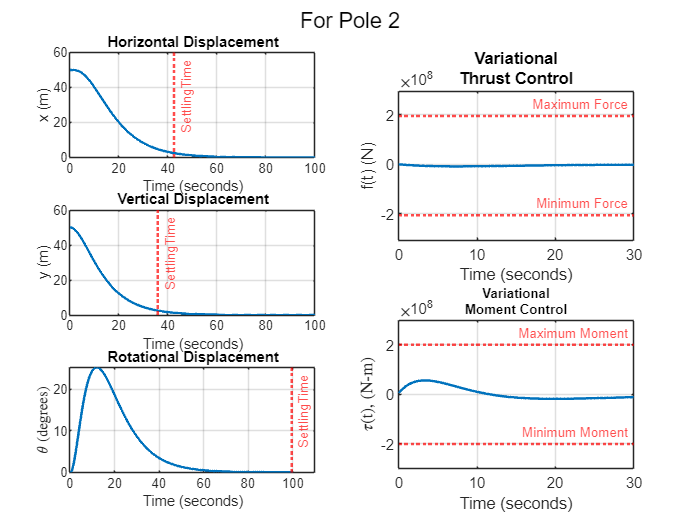

clf;

subplot(3,2,1);
plot(tOut2, y2(:,1), 'LineWidth', 1.5);
hold on;
xline(ST2(1,1), 'r:', 'LineWidth', 1.5, 'Label', 'SettlingTime', ...
    'LabelOrientation', 'aligned', 'FontSize', 8);
hold off;
xlim([0, max(tOut2)]);
xlabel('Time (seconds)');
ylabel('x (m)');
title('Horizontal Displacement');
grid on;
set(gca, 'Position', [0.1, 0.7, 0.35, 0.2]); % [left, bottom, width, height]


subplot(3,2,3);
plot(tOut2, y2(:,2), 'LineWidth', 1.5);
hold on;
xline(ST2(2,1), 'r:', 'LineWidth', 1.5, 'Label', 'SettlingTime', ...
    'LabelOrientation', 'aligned', 'FontSize', 8);
hold off;
xlim([0, max(tOut2)]);
xlabel('Time (seconds)');
ylabel('y (m)');
title('Vertical Displacement');
grid on;
set(gca, 'Position', [0.1, 0.4, 0.35, 0.2]);

subplot(3,2,5);
plot(tOut2, rad2deg(y2(:,3)), 'LineWidth', 1.5);
hold on;
xline(ST2(3,1), 'r:', 'LineWidth', 1.5, 'Label', 'SettlingTime', ...
    'LabelOrientation', 'aligned', 'FontSize', 8);
hold off;
xlim([0, max(tOut2) + 0.1*max(tOut2)]);
xlabel('Time (seconds)');
ylabel('$\theta$ (degrees)', 'Interpreter', 'latex');
title('Rotational Displacement');
grid on;
set(gca, 'Position', [0.1, 0.1, 0.35, 0.2]);
% Plot Variational Thrust Control
subplot(2,2,2);
plot(tOut2, y2(:,4), 'LineWidth', 1.5); % Use dashed line for the zero line
hold on;
yline(Fmax, 'r:', 'LineWidth', 1.5, 'Label', 'Maximum Force', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
yline(Fmin, 'r:', 'LineWidth', 1.5, 'Label', 'Minimum Force', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
hold off;
xlim([0, 30])
ylim([Fmin-1e8,Fmax+1e8])
xlabel('Time (seconds)');
ylabel('f(t) (N)');
title({'Variational', 'Thrust Control'});
grid on;
% Plot Variational Moment Control
subplot(2,2,4);

plot(tOut2, y2(:,5), 'LineWidth', 1.5);
hold on;
yline(Tmax, 'r:', 'LineWidth', 1.5, 'Label', 'Maximum Moment', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
yline(Tmin, 'r:', 'LineWidth', 1.5, 'Label', 'Minimum Moment', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
hold off;
xlim([0,30])
ylim([Tmin-1e8, Tmax+1e8])
xlabel('Time (seconds)');
ylabel('$\tau$(t), (N-m)', 'Interpreter', 'latex');
title({'Variational', 'Moment Control'},'FontSize', 8);
grid on;

sgtitle('For Pole 2');

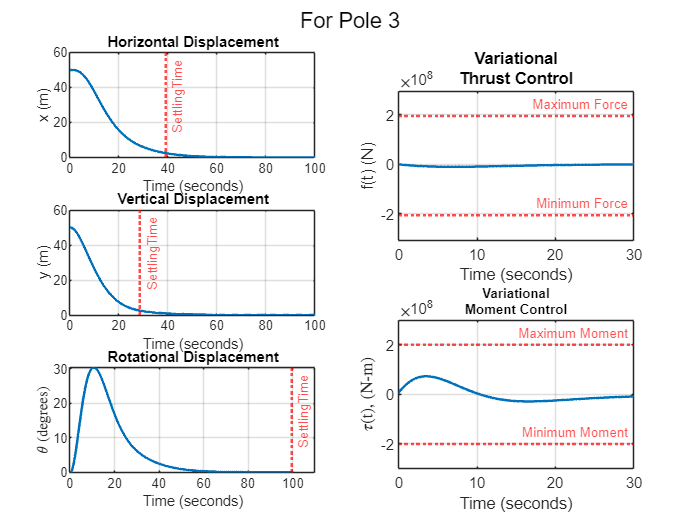

clf;

subplot(3,2,1);
plot(tOut3, y3(:,1), 'LineWidth', 1.5);
hold on;
xline(ST3(1,1), 'r:', 'LineWidth', 1.5, 'Label', 'SettlingTime', ...
    'LabelOrientation', 'aligned', 'FontSize', 8);
hold off;
xlim([0, max(tOut3)]);
xlabel('Time (seconds)');
ylabel('x (m)');
title('Horizontal Displacement');
grid on;
set(gca, 'Position', [0.1, 0.7, 0.35, 0.2]); % [left, bottom, width, height]


subplot(3,2,3);
plot(tOut3, y3(:,2), 'LineWidth', 1.5);
hold on;
xline(ST3(2,1), 'r:', 'LineWidth', 1.5, 'Label', 'SettlingTime', ...
    'LabelOrientation', 'aligned', 'FontSize', 8);
hold off;
xlim([0, max(tOut3)]);
xlabel('Time (seconds)');
ylabel('y (m)');
title('Vertical Displacement');
grid on;
set(gca, 'Position', [0.1, 0.4, 0.35, 0.2]);

subplot(3,2,5);
plot(tOut3, rad2deg(y3(:,3)), 'LineWidth', 1.5);
hold on;
xline(ST3(3,1), 'r:', 'LineWidth', 1.5, 'Label', 'SettlingTime', ...
    'LabelOrientation', 'aligned', 'FontSize', 8);
hold off;
xlim([0, max(tOut3) + 0.1*max(tOut3)]);
xlabel('Time (seconds)');
ylabel('$\theta$ (degrees)', 'Interpreter', 'latex');
title('Rotational Displacement');
grid on;
set(gca, 'Position', [0.1, 0.1, 0.35, 0.2]);
% Plot Variational Thrust Control
subplot(2,2,2);
plot(tOut3, y3(:,4), 'LineWidth', 1.5); % Use dashed line for the zero line
hold on;
yline(Fmax, 'r:', 'LineWidth', 1.5, 'Label', 'Maximum Force', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
yline(Fmin, 'r:', 'LineWidth', 1.5, 'Label', 'Minimum Force', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
hold off;
xlim([0, 30])
ylim([Fmin-1e8,Fmax+1e8])
xlabel('Time (seconds)');
ylabel('f(t) (N)');
title({'Variational', 'Thrust Control'});
grid on;
% Plot Variational Moment Control
subplot(2,2,4);

plot(tOut3, y3(:,5), 'LineWidth', 1.5);
hold on;
yline(Tmax, 'r:', 'LineWidth', 1.5, 'Label', 'Maximum Moment', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
yline(Tmin, 'r:', 'LineWidth', 1.5, 'Label', 'Minimum Moment', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
hold off;
xlim([0,30])
ylim([Tmin-1e8, Tmax+1e8])
xlabel('Time (seconds)');
ylabel('$\tau$(t), (N-m)', 'Interpreter', 'latex');
title({'Variational', 'Moment Control'},'FontSize', 8);
grid on;

sgtitle('For Pole 3');

clf;

subplot(3,2,1);
plot(tOut4, y4(:,1), 'LineWidth', 1.5);
hold on;
xline(ST4(1,1), 'r:', 'LineWidth', 1.5, 'Label', 'SettlingTime', ...
    'LabelOrientation', 'aligned', 'FontSize', 8);
hold off;
xlim([0, max(tOut4)]);
xlabel('Time (seconds)');
ylabel('x (m)');
title('Horizontal Displacement');
grid on;
set(gca, 'Position', [0.1, 0.7, 0.35, 0.2]); % [left, bottom, width, height]


subplot(3,2,3);
plot(tOut4, y4(:,2), 'LineWidth', 1.5);
hold on;
xline(ST4(2,1), 'r:', 'LineWidth', 1.5, 'Label', 'SettlingTime', ...
    'LabelOrientation', 'aligned', 'FontSize', 8);
hold off;
xlim([0, max(tOut4)]);
xlabel('Time (seconds)');
ylabel('y (m)');
title('Vertical Displacement');
grid on;
set(gca, 'Position', [0.1, 0.4, 0.35, 0.2]);

subplot(3,2,5);
plot(tOut4, rad2deg(y4(:,3)), 'LineWidth', 1.5);
hold on;
xline(ST4(3,1), 'r:', 'LineWidth', 1.5, 'Label', 'SettlingTime', ...
    'LabelOrientation', 'aligned', 'FontSize', 8);
hold off;
xlim([0, max(tOut4) + 0.1*max(tOut4)]);
xlabel('Time (seconds)');
ylabel('$\theta$ (degrees)', 'Interpreter', 'latex');
title('Rotational Displacement');
grid on;
set(gca, 'Position', [0.1, 0.1, 0.35, 0.2]);
% Plot Variational Thrust Control
subplot(2,2,2);
plot(tOut4, y4(:,4), 'LineWidth', 1.5); % Use dashed line for the zero line
hold on;
yline(Fmax, 'r:', 'LineWidth', 1.5, 'Label', 'Maximum Force', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
yline(Fmin, 'r:', 'LineWidth', 1.5, 'Label', 'Minimum Force', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
hold off;
xlim([0, 30])
ylim([Fmin-1e8,Fmax+1e8])
xlabel('Time (seconds)');
ylabel('f(t) (N)');
title({'Variational', 'Thrust Control'});
grid on;
% Plot Variational Moment Control
subplot(2,2,4);

plot(tOut4, y4(:,5), 'LineWidth', 1.5);
hold on;
yline(Tmax, 'r:', 'LineWidth', 1.5, 'Label', 'Maximum Moment', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
yline(Tmin, 'r:', 'LineWidth', 1.5, 'Label', 'Minimum Moment', ...
    'LabelOrientation', 'horizontal', 'FontSize', 8);
hold off;
xlim([0,30])
ylim([Tmin-1e8, Tmax+1e8])
xlabel('Time (seconds)');
ylabel('$\tau$(t), (N-m)', 'Interpreter', 'latex');
title({'Variational', 'Moment Control'},'FontSize', 8);
grid on;

sgtitle('For Pole 4');

Use the animation function `als_f24_animate.p` to animate the time response of each design as supplemental documentation of your results.

als_f24_animate(tOut1, y1(:,1), y1(:,2), y1(:,3));

## **Appendix**

`function A = polePlacement(zeta, omega, truthVal)`

`% for constant damping line, truthVal = 1`

`% and for constant frequency line truthVal = 0`

`A =[];`

`truthVal = logical(truthVal);`

`if isequal(truthVal,1)`

`    for i =1:3`

`        s1 = -zeta*(omega+((i-1)*0.1))+(omega+((i-1)*0.1))*sqrt(1-zeta^2)*1j;`

`        s2 = -zeta*(omega+((i-1)*0.1))-(omega+((i-1)*0.1))*sqrt(1-zeta^2)*1j;`

`        A = [A,s1,s2];`

`    end    `

`else`

`    for i =1:3`

`        s1 = -(zeta+((i-1)*0.001))*omega+omega*sqrt(1-(zeta+((i-1)*0.001))^2)*1j;`

`        s2 = -(zeta+((i-1)*0.001))*omega-omega*sqrt(1-(zeta+((i-1)*0.001))^2)*1j;`

`        A = [A,s1,s2];`

`    end`

`end`

`end`